Example of dilation with a linear mapping and uniform scaling

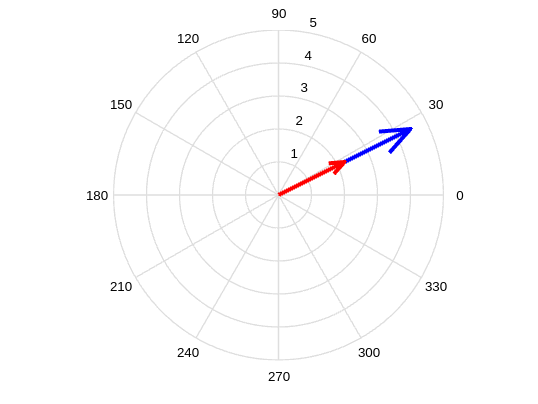

clf;
rho=2;
A=rho*eye(2);
x=[2 1]';
y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

Example of non uniform scaling

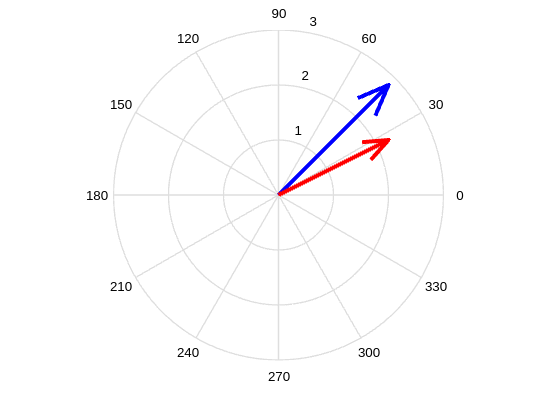

clf;
A=diag([1 2]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

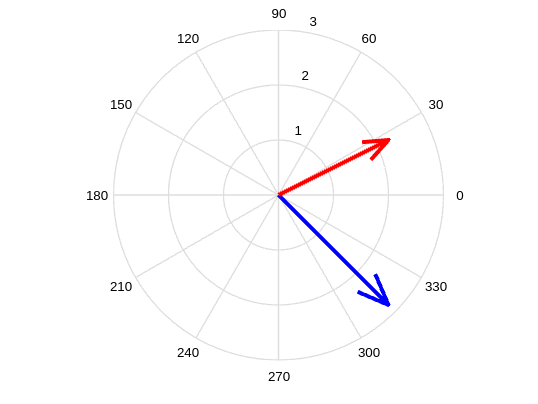


clf;
A=diag([1 -2]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h,'LineWidth',3); hold on; axis('tight');
h=compass(x(1),x(2),'r'); set(h,'LineWidth',3);

disp(y);

       2       
      -2       



A=diag([1 -1])

A =        1              0       
       0             -1       


xa=[2 -1]';
xb=[3 3]';
xc=[xa xb]

xc =        2              3       
      -1              3       


%disp(A*xa);
%disp(A*xb);
disp(A*xc); % Change the sign of the last rows

       2              3       
       1             -3       



clf;

Reflection over y axis

A=diag([-1 1])

A =       -1              0       
       0              1       


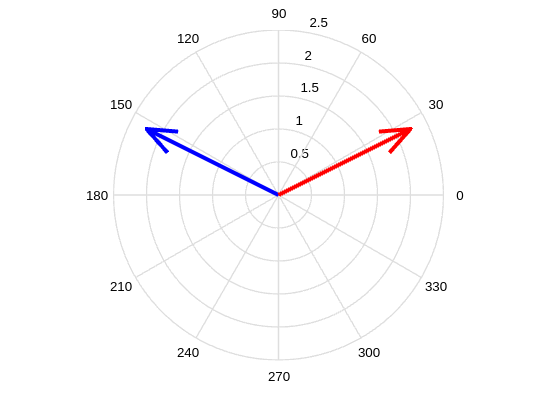

x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

Reflection over x -axis

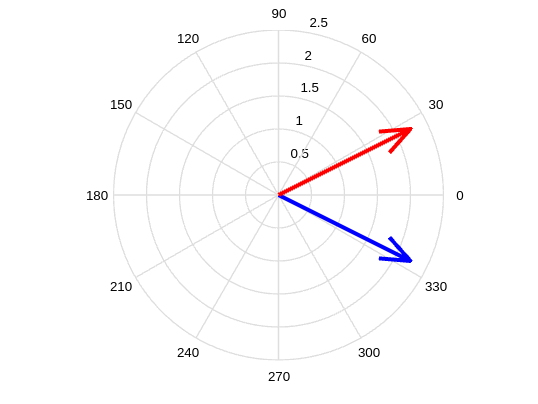

clf;
A=diag([1 -1]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

Reflection over origin

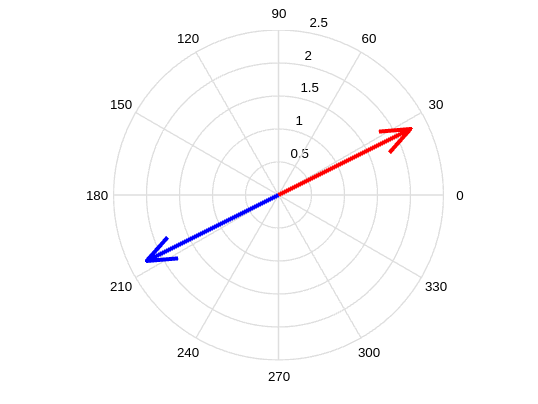

clf;
A=diag([-1 -1]);
x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b');
set(h,'LineWidth',3)
hold on; axis('tight')
h=compass(x(1),x(2),'r');
set(h,'LineWidth',3)

a=[1 0]'; syms lambda real
syms x y [2 1] real
P1=x+y-lambda*a; P2=a'*(x-y);
Y=solve(P2,P1(2),y1,y2);
y=[Y.y1;Y.y2]

$$y = \left(\begin{array}{c} x_{1}\\ -x_{2} \end{array}\right)$$


A=zeros(2);
for k=1:2
	if simplify(symvar(y(k)) == x1)
		A(k,1)=y(k)/x1;
	end
	if simplify(symvar(y(k)) == x2)
		A(k,2)=y(k)/x2;
	end
end

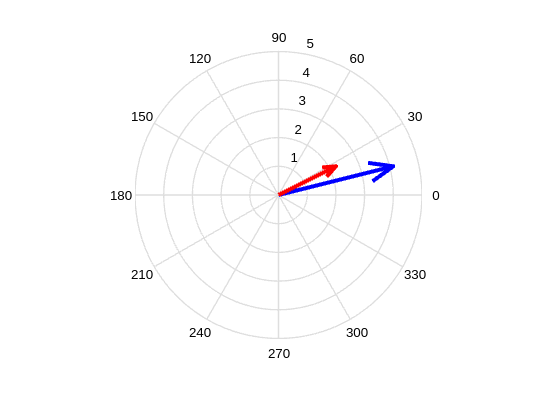

clf;
A=[1 2;0 1]; x=[2 1]'; y=A*x;
h=compass(y(1),y(2),'b'); set(h, 'LineWidth',3); hold on; grid on;
h=compass(x(1),x(2),'r'); set(h, 'LineWidth',3);

x=[-2 1]'; y=A*x;

clf;

A=[1 2;0 1]; x=[0 1]'; y=A*x

y =        2       
       1       


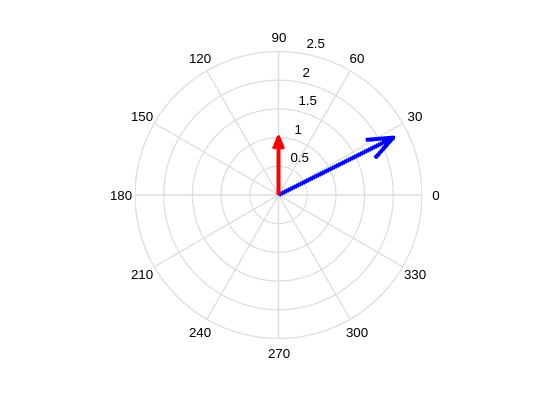

h=compass(y(1),y(2),'b'); set(h, 'LineWidth',3); hold on; grid on;
h=compass(x(1),x(2),'r'); set(h, 'LineWidth',3);


th=acos(dot(x,y)/(norm(x)*norm(y))); disp(tan(th));

       2       



clf;

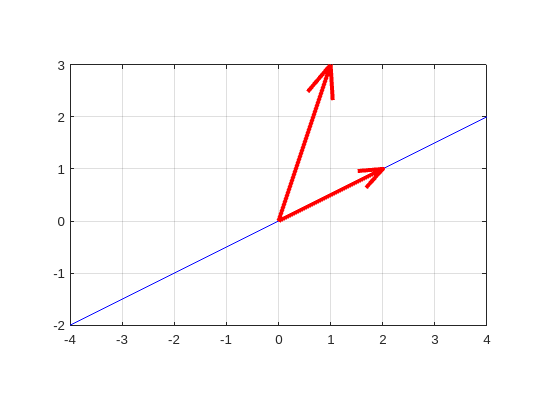

clf;
a=[2 1]'; syms b real; r=b*a; A=[a*a'/norm(a)^2];
x=[1 3]'; y=A*x; n=null(a'); % normal
fplot(r(1),r(2),[-2 2],'Color','b'); hold on
h=compass([x(1) y(1)],[x(2) y(2)] ,'r'); set(h, "LineWidth",3); hold on;
axis equal; grid on;

fplot(a(1)+n(1),a(2)+n(2), [-1 2.5],'Color','c','LineStyle','--');

Error using fplot
Invalid parameter '1.8944'.

## 3D Rotations

R=[-1 0 0;0 0 -1;0 1 0]

R =     -1     0     0
     0     0    -1
     0     1     0


disp([R'*R R*R']) %Orthogonal Matrix Verified

     1     0     0     1     0     0
     0     1     0     0     1     0
     0     0     1     0     0     1



disp(det(R)) %Improper rotation

    -1





P=[1 0 0;0 0 1;0 1 0]

P =      1     0     0
     0     0     1
     0     1     0


R1=R*P

R1 =     -1     0     0
     0    -1     0
     0     0     1


det(R1)

ans = 1


%What kind of linear transformation does the permutation matrix P induce?
%Answ: Symmetric 
%What does P^(-1) do??

R2=R'*P

R2 =     -1     0     0
     0     1     0
     0     0    -1


det(R2) %Det is 1 so the rotation is proper

ans = 1

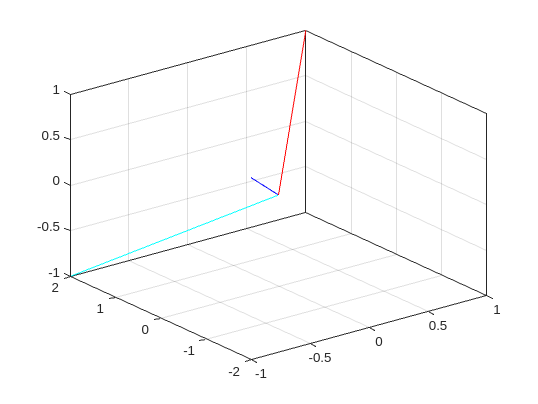


x=[1 2 1]';
clf;
plot3([0 x(1)],[0 x(2)],[0 x(3)],'Color','r','LineStyle','-');
hold on; axis on; box on; grid on;
r1x=R1*x;
plot3([0 r1x(1)],[0 r1x(2)],[0 r1x(3)],'Color','b','LineStyle','-');
r2x=R2*x;
plot3([0 r2x(1)],[0 r2x(2)],[0 r2x(3)],'Color','c','LineStyle','-');

clf;
a=[3 2 1]'; syms t real;
ezplot3(t*a(1),t*a(2),t*a(3),[-2 2])
axis equal; hold on; box on
h=quiver3(0,0,0,a(1),a(2),a(3),1); set(h,'LineWidth',3);

A = 2/norm(a)^2*a*a'-eye(size(a,1))

A =     0.2857    0.8571    0.4286
    0.8571   -0.4286    0.2857
    0.4286    0.2857   -0.8571


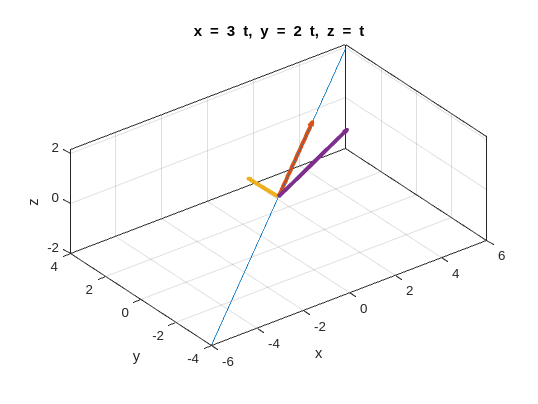

x=[1 3 -1]'; y=A*x;
h=quiver3(0,0,0,x(1),x(2),x(3),1); set(h,'LineWidth',3);
h=quiver3(0,0,0,y(1),y(2),y(3),1); set(h,'LineWidth',3);

disp(det(A)); %A reflection with det(A)=1 is a rotation around its axis by an angle = + or - pi

    1.0000




disp(eig(A)); %eigenvalues -1,1

   -1.0000
   -1.0000
    1.0000



disp(A*A) %The matrix equals its inverse

    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000



disp(A'*A)

    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000



disp(A*A')

    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000




ax=null(A-eye(3)); %Rotation axis
disp(rank([a ax]));

     1



cosTH=(trace(A)-1)/2;
sinTH=(A(1,3) - (1-cosTH)*ax(1)*ax(3)/ax(2));
TH=atan2(sinTH,cosTH)*180/pi 

TH = 129.1033

## Generalized Inverse

A=[1 2;2 4;3 6] 

A =      1     2
     2     4
     3     6


G=[1 0 0;0 0 0];
disp(A*G)

     1     0     0
     2     0     0
     3     0     0



disp(G*A)

     1     2
     0     0



AGA=A*G*A;
disp(AGA)

     1     2
     2     4
     3     6



NA=null(sym(A));
syms a b c real
G1=G + NA*[a b c]

$$G1 = \left(\begin{array}{ccc} 1-2\,a & -2\,b & -2\,c\\ a & b & c \end{array}\right)$$

AG1A=A*G1*A

$$AG1A = \left(\begin{array}{cc} 1 & 2\\ 2 & 4\\ 3 & 6 \end{array}\right)$$

Generalized inverses of a matrix: example 1

A=sym([1 2 3;4 5 6;7 8 9]);
[m,n]=size(A);
r=rank(A)

r = 2

S=rref(A)

$$S = \left(\begin{array}{ccc} 1 & 0 & -1\\ 0 & 1 & 2\\ 0 & 0 & 0 \end{array}\right)$$

Ar=A(1:2,1:2)

$$Ar = \left(\begin{array}{cc} 1 & 2\\ 4 & 5 \end{array}\right)$$

rank(Ar)

ans = 2

% ---
B=A(1:2,3)

$$B = \left(\begin{array}{c} 3\\ 6 \end{array}\right)$$

C=A(3,1:2)

$$C = \left(\begin{array}{cc} 7 & 8 \end{array}\right)$$

D=C*inv(Ar)*B

$$D = 9$$

G=[inv(Ar) zeros(r,m-r); zeros(n-r,m)]

$$G = \left(\begin{array}{ccc} -\frac{5}{3} & \frac{2}{3} & 0\\ \frac{4}{3} & -\frac{1}{3} & 0\\ 0 & 0 & 0 \end{array}\right)$$

all(all(isAlways(A*G*A==A))) %check

ans = logical
   1



%Is G unique?
NA=null(A); syms a b c real;
G1=G+NA*[a b c];
all(all(isAlways(A*G1*A==A))) %Infinitely many g-inverses

ans = logical
   1


## Pseudoinverse

A=[1 2 0; 0 1 1];
[U,S,V]=svd(A);
%[U,S,V]=svd(A,'econ');
Sp=[inv(S(:,1:2));zeros(1,2)];
Ap=V*Sp*U'

Ap =     0.3333   -0.3333
    0.3333    0.1667
   -0.3333    0.8333


%check now with pinv
pinv(A)

ans =     0.3333   -0.3333
    0.3333    0.1667
   -0.3333    0.8333


Another way to calculate the pseudoinverse (avoiding computing the inverse) is:

[U,S,V]=svd(A);
Sp=[diag(diag(S(:,1:2).^-1));zeros(1,2)];
Ap=V*Sp*U;
disp(Ap)

    0.6000   -0.8000
    2.0000   -1.0000
    0.8000    0.6000



example 2 of pseudoinverse

A=sym([1 2 3;4 5 6;7 8 9]);
rank(A);

Ps=pinv(A);
all(all(isAlways(A*Ps*A == A))) %Verify property 1

ans = logical
   1


all(all(isAlways(Ps*A*Ps == Ps))) %Verify property 2

ans = logical
   1


all(all(isAlways((A*Ps)' == A*Ps))) %Verify symmetry 1

ans = logical
   1


all(all(isAlways((Ps*A)' == Ps*A))) %Verify symmetry 2

ans = logical
   1


Verify uniqueness:

NA=null(A); syms a b c real
assumeAlso(a>0 & b>0 & c>0);
P1=Ps + NA*[a b c];
all(all(isAlways(A*P1*A == A))) %Ok

ans = logical
   1


eig(P1*A*P1-P1)' % Property two doesn't Hold

$$ans = \left(\begin{array}{ccc} 0 & 0 & 2\,b-a-c \end{array}\right)$$

all(all(isAlways((P1*A)' == P1*A))) %Property 4 doesn't hold

ans = logical
   0


G is a generalized inverse of A

S=rref(A)

$$S = \left(\begin{array}{ccc} 1 & 0 & -1\\ 0 & 1 & 2\\ 0 & 0 & 0 \end{array}\right)$$

[m,n]=size(A);
r=rank(A)

r = 2

Ar=A(1:2,1:2);
G=[inv(Ar) zeros(r,m-r); zeros(n-r,m)]

$$G = \left(\begin{array}{ccc} -\frac{5}{3} & \frac{2}{3} & 0\\ \frac{4}{3} & -\frac{1}{3} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Check pseudoinverse definition properties:

all(all(isAlways(A*G*A == A))) %(1) holds

ans = logical
   1


all(all(isAlways(G*A*G == G))) %(2) Holds

ans = logical
   1


all(all(isAlways((A*G)' == A*G)))  %(3) doesn't hold

ans = logical
   0


all(all(isAlways((G*A)' == G*A))) %(4) doesn't hold

ans = logical
   0


Right inverses of a maximum rank matrix

A=[1 2 0; 0 1 1];
[m,n]=size(A);
format rational
xp=A\eye(2) %particular solutions

xp =        0              0       
       1/2            0       
      -1/2            1       


xn=null(A,"rational")

xn =        2       
      -1       
       1       



syms a b real
C=xp + xn*[a b] %General right inverse

$$C = \left(\begin{array}{cc} 2\,a & 2\,b\\ \frac{1}{2}-a & -b\\ a-\frac{1}{2} & b+1 \end{array}\right)$$

disp(A*C)

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

disp(A*xp) %Particular right inverse

       1              0       
       *              1       

